load("Guitar.MAT")
plot(wave2proc)
plot(realwave)
%sound(wave2proc)
sound(realwave)

%  第二部分问题1

[song,fs]=audioread("fmt.wav")
sound(song,fs)

%第二部分问题2


%去除真实音乐中的非线性谐波和噪声

load("Guitar.MAT")

%原音乐中大致含有十个相同周期，将原声采样点增加到10的整数倍，方便在每一个周期
%内取相同位置点的值做平均 获得一个平均周期的情况
%然后复制平均周期至全部周期内

song=resample(realwave,10,1);


len=length(realwave)

len = 243

new_song=0*realwave; %一个单周期的空白数组 获得平均周期 便于后续进行10个周期复制
for i=1:len
    for k=0:9
        new_song(i)=new_song(i)+song(i+k*len); %新周期的第i点值是十个周期i i+len i+2len ... i+9len 的和的均值
    end
    new_song(i)=new_song(i)/10;
end
% 上面循环得到一个平均周期

new_f=repmat(new_song,10,1); % 横向复制10次 纵向仅一次

new_wave2=resample(new_f,1,10)

new_wave2 =     0.0698
    0.2237
    0.2040
    0.1322
    0.0529
    0.0236
   -0.0263
   -0.0474
   -0.0290
   -0.0747


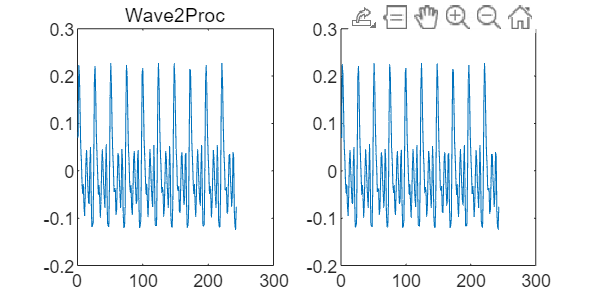

% 
% plot(wave2proc)
% plot(new_wave2)
figure('Position', [100 100 800 400]); % 这里的参数是[left bottom width height]  
  
% 使用subplot在左侧创建一个子图  
subplot(1, 2, 1); % 1行2列，当前是第1个子图  
plot(wave2proc); % 绘制wave2proc的数据  
title('Wave2Proc'); % 添加标题  
  
subplot(1, 2, 2);
plot( new_wave2); % 在新的轴上绘制new_wave2的数据  
title( 'NewWave2'); % 为新的轴添加标题  

%很接近

%第二部分问题3

len=length(realwave) %243 取一个周期 即24个采样点

len = 243

fs=8000

fs = 8000

s_1=realwave(1:24)

s_1 =     0.1190
    0.2271
    0.1919
    0.0927
    0.0096
   -0.0197
   -0.0691
   -0.0956
   -0.0784
   -0.1271


s1_f=fft(s_1)/24;
fft_req=(1:12)*fs/24;
  %绘制半频谱

s_2=realwave;   %取原来的全信号进行fft
s2_f=fft(s_2)/len;
fft_req1=(1:len/2)*fs/len;


s_3=repmat(realwave,10,1) %原来全信号扩展10次进行fft

s_3 =     0.1190
    0.2271
    0.1919
    0.0927
    0.0096
   -0.0197
   -0.0691
   -0.0956
   -0.0784
   -0.1271


len1=length(s_3)

len1 = 2430

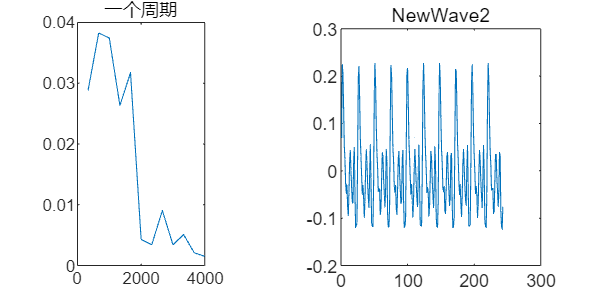

s3_f=fft(s_3)/len1;
fft_req2=(1:len1/2)*fs/len1;

f=fft_req2;
%复制次数越多 越接近周期函数 频谱变成冲击函数的组合
% fff=abs(s3_f(1:len1/2));
% f_index = mqy_find_peak(fff,45,0.01*max(fff));
% 
% A = mqy_recognize(f(f_index),fff(f_index)); 
% 使用subplot在左侧创建一个子图  
subplot(1, 3, 1); % 1行2列，当前是第1个子图  
plot(fft_req,abs(s1_f(1:12)));   
title('一个周期'); % 添加标题  

  
subplot(1, 3, 2);
plot(fft_req1,abs(s2_f(1:len/2))); 

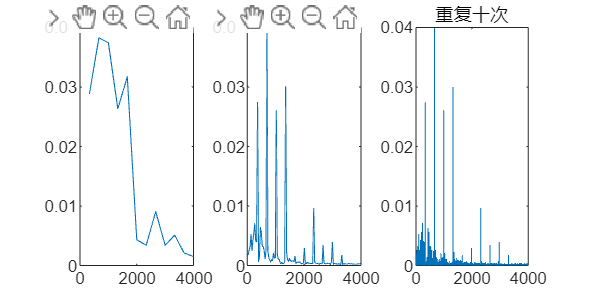

title( '整个信号'); % 为新的轴添加标题  

subplot(1, 3, 3);
plot(fft_req2,abs(s3_f(1:len1/2)));
title( '重复十次'); % 为新的轴添加标题  